# Exemples de imatges

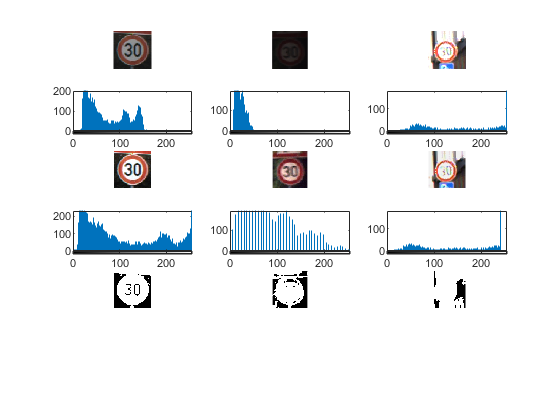

img1 = imread("Train1\Train1\1\00001_00010_00026.png"); %imatge OK
img2 = imread("Train1\Train1\1\00001_00012_00018.png"); %obscura
img3 = imread("Train1\Train1\1\00001_00071_00000.png"); %molta llum

desc = 6;
aux = 1;

figure
subplot(desc, 3, aux)
imshow(img1)
subplot(desc, 3, aux+1)
imshow(img2)
subplot(desc, 3, aux+2)
imshow(img3)

aux = aux + 3;

subplot(desc, 3, aux)
imhist(img1)
subplot(desc, 3, aux+1)
imhist(img2)
subplot(desc, 3, aux+2)
imhist(img3)

aux = aux + 3;

%imshow normalize
subplot(desc, 3, aux)
normImg1 = normalize(img1);
imshow(normImg1);
subplot(desc, 3, aux+1)
normImg2 = normalize(img2);
imshow(normImg2);
subplot(desc, 3, aux+2)
normImg3 = normalize(img3);
imshow(normImg3);

aux = aux + 3;

%imhist normalize
subplot(desc, 3, aux)
imhist(normImg1)
subplot(desc, 3, aux+1)
imhist(normImg2)
subplot(desc, 3, aux+2)
imhist(normImg3)

aux = aux + 3;


%iluminación:
subplot(desc, 3, aux)
lab1 = rgb2lab(normImg1);
lab1(lab1(:,:,1) > 90) = 100;
lab1(lab1(:,:,1) < 25) = 0;
imshow(lab1(:,:,1));

subplot(desc, 3, aux+1)
lab2 = rgb2lab(normImg2);
lab2(lab2(:,:,1) > 90) = 100;
lab2(lab2(:,:,1) < 25) = 0;
imshow(lab2(:,:,1));

subplot(desc, 3, aux+2)
lab3 = rgb2lab(normImg3);
lab3(lab3(:,:,1) > 90) = 100;
lab3(lab3(:,:,1) < 25) = 0;
imshow(lab3(:,:,1));


aux = aux + 3;